Import necessary files

close all; % close open MATLAB windows
clear; % clear active MATLAB variables
path(pathdef); % reset to default PATH environment
addpath("./Plotters"); % add Plotters directory to PATH

Retreive 2D matrix of traces from results files

filepaths = [ ...
    "C:\Marcinik\Tracking\Data\Martin\SO After\_res1.mat"
    "C:\Marcinik\Tracking\Data\Martin\SO After\_res2.mat"
    "C:\Marcinik\Tracking\Data\Martin\SO After\_res3.mat"
    "C:\Marcinik\Tracking\Data\Martin\SO After\_res4.mat"
    "C:\Marcinik\Tracking\Data\Martin\SO After\_res5.mat"
    "C:\Marcinik\Tracking\Data\Martin\SO After\_res6.mat"
    ];
traces = ResultsParser.traceArrayFromFilepaths(filepaths);

Generate and display a waterfall plot with optional offset

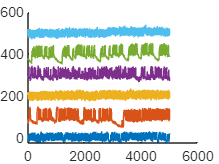

PlotFromTraceArray.waterfall(traces, "Offset", 100);